## 8.6   符号方程与求解

### 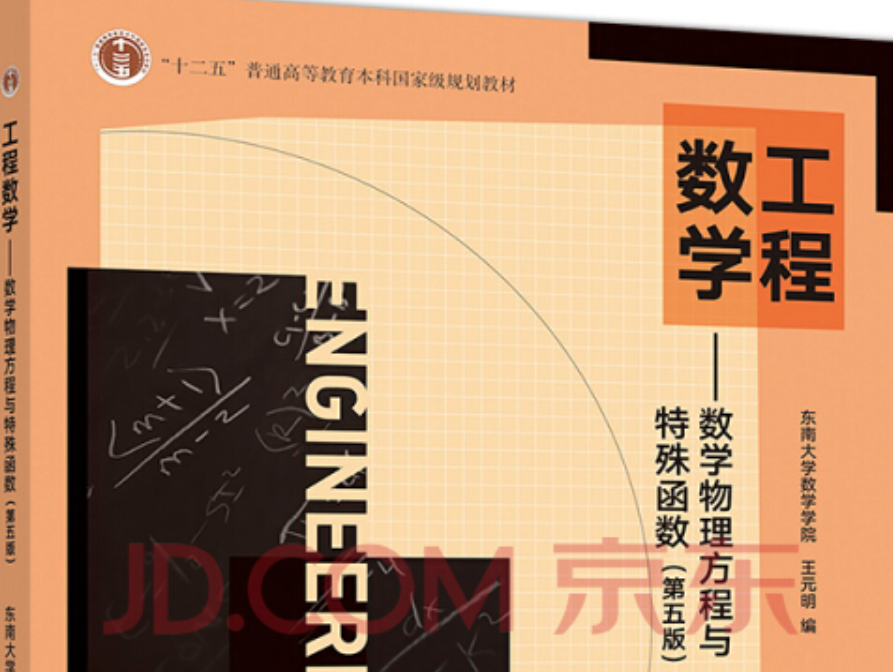

包括简单方程的求解：多元一次方程、线性方程组：使用函数**solve**

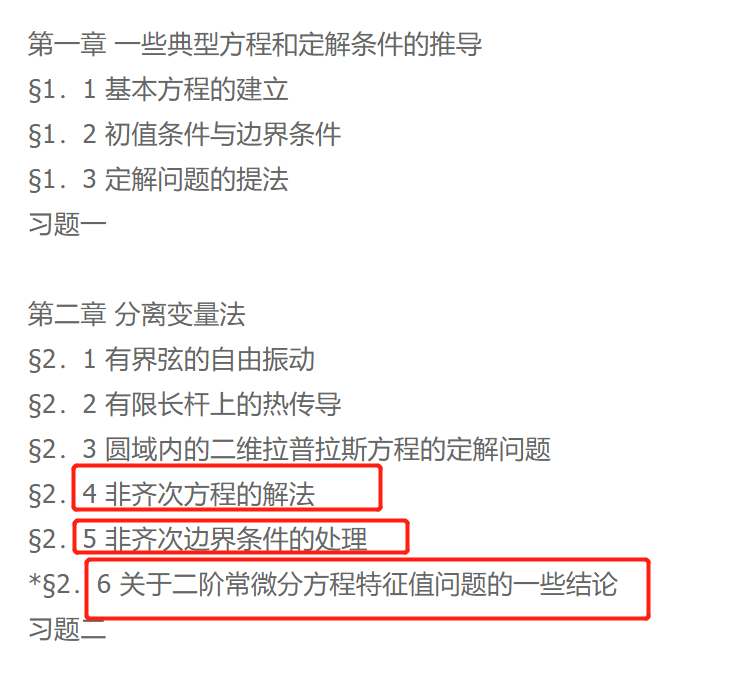，微分方程组： 使用函数**dsolve**

### **8.6.1   符号代数方程求解**

代数方程包括线性方程、非线性方程和超越方程等。

**1．解代数方程**

在MATLAB 中， solve() 函数用于求解代数方程和方程组，其调用格式如下：

- g = solve(eq) 。对默认自变量 x 求解，求方程符号eq 的解，输入参数 eq 可以是符号表达式或字符串，即 solve(eq) 对方程 eq 中的默认变量 x ，求解方程 eq=0 。若输出参量g 为单一变量，则对于有多重解的非线性方程， g 为一行向量。

- solve(eq,var,value) 。求解方程  eq  的解，对指定自变量 var 求解。例如 g=solve(x^2-1)  或 g=solve(x^2-1,x,0)  或g=solve(x^2-1,0) 。

对于单个方程的情况，返回结果为一个符号表达式，或是一个符号表达式组成的数组。

## **例  求一元二次方程 **${\textrm{ax}}^2 +\textrm{bx}+c=0$** 的根。**

解  程序如下：

syms a b c x
f=a*x^2+b*x+c

$$f = a\,x^{2}+b\,x+c$$

solve(f)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

即方程 ${\textrm{ax}}^2 +\textrm{bx}+c=0$ 的根为$x = \frac{{ - b \pm \sqrt {{b^2} - 4ac} }}{{2a}}$

`如果把a作为自变量求解，则结果如下：`

solve(f, a)

ans= - (b*x+c)/x^2

**2 ．代数方程组的符号解法**

代数方程组同样使用 solve() 函数进行求解。

对于方程组的情况，返回结果为一个结构体，结构体的元素为每个变量对应的表达式，各个变量按照字母顺序排列，其格式如下：

- solve(eq1,eq2,...,eqn) 。求由方程 eq1 、 eq2 、…、eqn 等组成的系统，自变量为默认自变量；

- solve(eq1,eq2,...,eqn,var1,var2,...,varn) 。求由方程 eq1 、 eq2 、…、 eqn 等组成的系统，自变量为指定的自变量： var1 、 var2 、…、 varn 。

## 例  求 $\left\{ \begin{array}{l}
x + y = 1\\
x - 11y = 5
\end{array} \right.$   的解。

解  程序如下：

syms x y
f1 = x^2+y-1
f2 = x-11*y-5
S = solve(f1,f2)
S.x        

Unable to resolve the name S.x.

S.y     

## 例     求微分方程：$$\frac{{dx}}{{dt}} =  - ax$$和$$\frac{{{d^2}x}}{{d{t^2}}} =  - ax$$

解   语法如下：

syms a x(t);
eqn1 = diff(x,t) == -a*x;
s1 = dsolve(eqn1)

$$s1 = C_{1}\,{\mathrm{e}}^{-a\,t}$$

eqn2 = diff(x,t,2) == -a*x;
s2 = dsolve(eqn2)

$$s2 = C_{1}\,{\mathrm{e}}^{\sqrt{-a}\,t}+C_{2}\,{\mathrm{e}}^{-\sqrt{-a}\,t}$$

结果为：

s1 =

C1*exp(-a*t)

s2 =

C1*exp((-a)^(1/2)*t) + C2*exp(-(-a)^(1/2)*t)

## 例     求微分方程 $y\prime =x$ 的通解。

解   程序如下：

syms x y(x)    %定义x， y 为符号
eqn1 = diff(y) == x;
y = dsolve(eqn1)

`结果为：`

y =

x^2/2 + C1

## 例    求微分方程 $\[\left\{ \begin{array}{l}
y'' = x + y'\\
y(0) = 1,{\rm{  }}y'(0) = 0
\end{array} \right.\]$的特解。

解   程序如下：

syms x y(x)
eqn = diff(y,x,2) == x + diff(y,x);
Dy = diff(y);
cond = [y(0) == 1, Dy(0) == 0];
S = dsolve(eqn,cond)

结果是：

S =

exp(x) - x - x^2/2

#### 2 ．微分方程组的求解

微分方程组通过 dsolve() 函数进行求解，格式为：

r = dsolve(eq1,eq2,..., cond1,cond2,..., v)

该语句求解由参数 eq1 、 eq2 等指定的方程组成的系统，初值条件为 cond1 、 cond2 等， v 为自变量

## 例     求微分方程组$$\left\{ \begin{array}{l}
x' = x + y\\
y' = 2x
\end{array} \right.$$ 的通解。

解   程序如下：

syms x(t) y(t)
eqn1 = diff(x,t) == y + x;
eqn2 = diff(y,t) == 2 * x;
[x y] = dsolve(eqn1,eqn2)

结果为

x = -  1/2*C1*exp(-  t)+C2*exp(2*t)

y =C1*exp(-  t)+C2*exp(2*t)

## 例  求微分方程组：$$\left\{ \begin{array}{l}
u' = v\\
v' = w\\
w' =  - u
\end{array} \right.$$， $u\left(0\right)=0,\;v\left(0\right)=0,\;w\left(0\right)=1$ 的结果。

解  程序如下：

syms u(t) v(t) w(t);
eqn = [diff(u) == v, diff(v) == w, diff(w) == -u];
cond = [u(0) == 0; v(0) == 0; w(0) == 1];
S = dsolve(eqn, cond)

结果为一个结构：

S = 

u: [1x1 sym]

v: [1x1 sym]

w: [1x1 sym]

可用查询结构成员的方法，查询结果：

S.u

ans =

1/(3*exp(t)) -

(cos((3^(1/2)*t)/2)*exp(t)^(3/2))/(3*exp(t))

+ (3^(1/2)*sin((3^(1/2)*t)/2)*exp(t)^(3/2))/(3*exp(t))

## 8.7   符号函数图形绘制

### 8.7.1   符号函数二维绘图函数 fplot()

1 ．显函数的调用

对于显函数，其调用格式如下：

- fplot(f) 。绘制函数 f 在区间 (-5≤x≤5) 内的图形， f 可以是函数句柄或串。

- fplot(f,[min,max]) 。绘制函数 f 在指定区间 [min, max]内的图形。

2 ．隐函数的调用

隐函数定义为 fun2(x,y) ， fplot() 函数的调用格式如下：

- fplot(fun2) ：绘制函数 fun2(x,y)=0 在区间(-5≤x≤5)的图形。

- fplot(fun2,[TMIN TMAX]) ：绘制函数 fun2(x,y)=0， x(t) 和 y(t) 的取值范围由 tmin < t < tmax 决定。

## 例   MATLAB 中符号计算中提供单位阶跃函数 heaviside(t-a) 、斜坡可以使用阶跃和直线方程构成。

解   (1)  绘制a=4 时的阶跃函数。

syms t
f=@(t)heaviside(t-4);
fplot(f,[0 5]) %

(2)  在t=1 时发生转折斜率为 1 的斜坡可以表示为

f=@(t)t.*heaviside(t-1)-heaviside(t-1);
fplot(f,[0 3])

绘制出斜坡函数曲线。

3 ．参数方程的调用

对于参数方程， fplot() 函数的调用格式有：

- fplot(x,y) ：绘制参数方程 x = x(t) 、 y = y(t) 在 (0 <t < 2 ）的曲线。

- fplot(x,y,[tmin,tmax]) ：绘制参数方程  x = x(t) 、 y= y(t) 在tmin < t < tmax 的曲线。

### **8.7.2   符号函数三维绘图函数 fplot3()**

fplot3() 函数用于绘制三维参数曲线。该函数的调用格式如下：

- fplot3(x,y,z) 。在默认区间 (0<t <2p  内绘制参数方程x = x(t) 、 y = y(t)、 z = z(t) 的图像。

- fplot3(x,y,z,[tmin,tmax]) 。在区间 tmin<t<tmax 内绘制参数方程 x = x(t) 、 y = y(t) 、 z = z(t)  的图像。

## 例   绘制空间曲线的动态轨迹。

解  程序如下：

syms x y t z
x= sin(t);y= cos(t);z=t;
fplot3(x,y,z,[0,6*pi])

生成空间曲线的动态轨迹。

### 8.7.3   符号函数曲面网格图及表面图的绘制

1 ． fmesh() 、 fsurf() 函数

fmesh() 、 fsurf() 函数分别用于绘制三维网格图和三维表面图。这两个函数的用法相同，下面以函数 ezmesh() 函数为例介绍三维曲面的绘制。该函数的调用格式如下：

- fmesh(f) ：绘制函数 f(x,y) 在默认区域 -5≤x≤5 、-5≤y≤5内的图像。

- fmesh(f,domain) ：在 domain 指定区域绘制函数 f(x,y) 的图像；

- fmesh(x,y,z) ：在默认区域 -5≤s≤5 、-5≤t≤5 内，绘制三维参数方程 x = x(s,t) ， y = y(s,t) ， and z = z(s,t) 的图形。

- fmesh(x,y,z,[smin,smax,tmin,tmax]) 或fmesh(x,y,z,[min,max]) ：在指定区域绘制三维参数方程的图像。

## 例 已知函数$$f(x,y) = x{e^{ - {x^2} - {y^2}}}$$，绘制三维网格图。

解  程序如下：

syms x y
fh = @(x,y) x.*exp(-x.^2-y.^2);
fmesh(fh)
colormap([0 0 1])

绘制出的三维网格图。